clear, clc, format short g


## PARTE 1

## 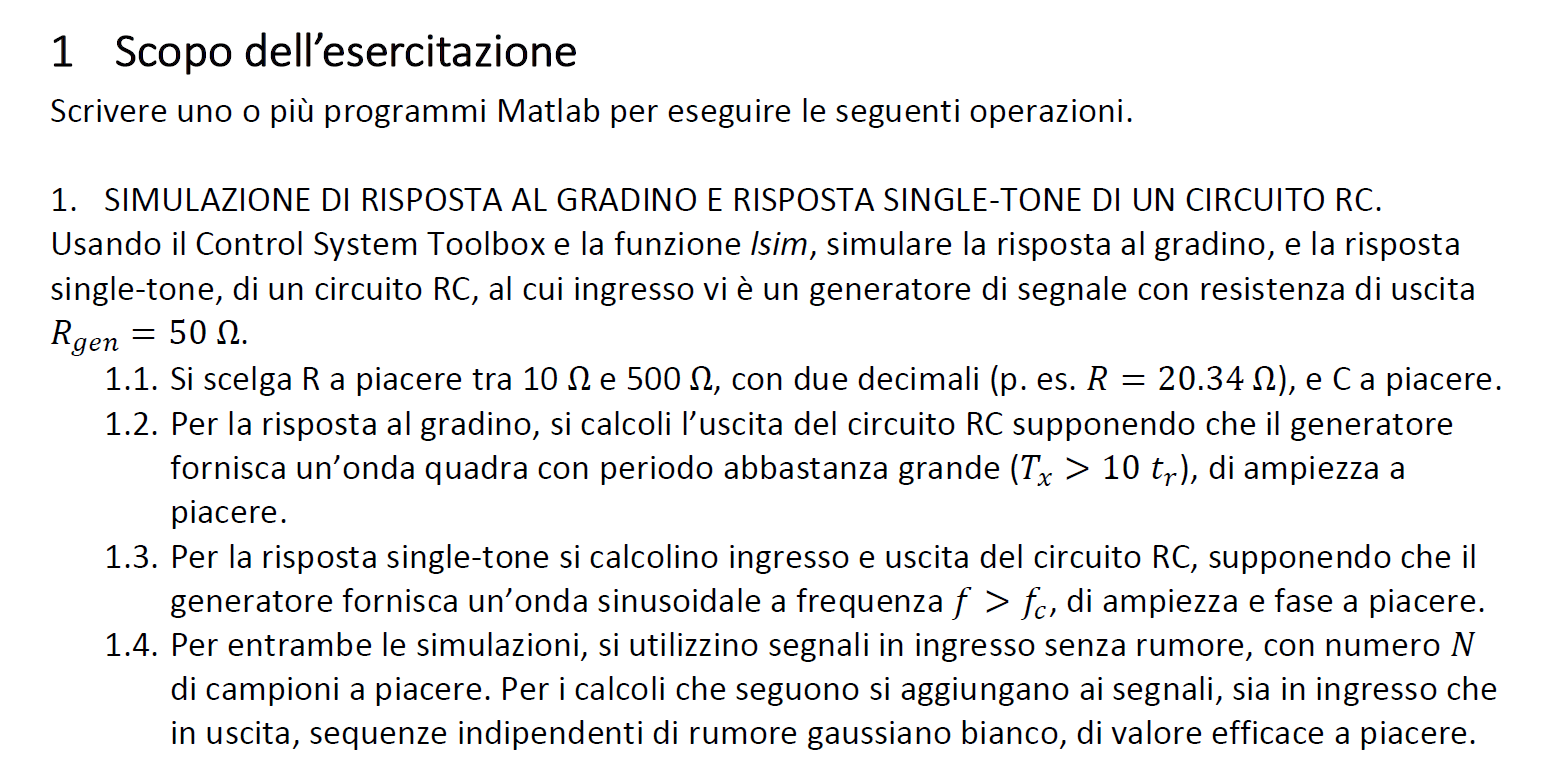


Rgen = 50;
R = 74.38;
C = 15e-9;

tr = C*(R+Rgen)*log(9)

tr =    4.0994e-06



N = 1000;

## definizione tau


tau_step = R*C;
tau_sin = (R+Rgen)*C

tau_sin =    1.8657e-06


## definizione periodi di campionamento

Td = 11*tr % durata simulazione

Td =    4.5093e-05



Ts = Td/N %periodo di campionamento

Ts =    4.5093e-08



n = (0:N-1)' %indici di campionamento

n =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9



t = n*Ts % istanti di campionamento

t =             0
   4.5093e-08
   9.0186e-08
   1.3528e-07
   1.8037e-07
   2.2546e-07
   2.7056e-07
   3.1565e-07
   3.6074e-07
   4.0584e-07


## definizione onda quadra in ingresso

Vpp = 10;

x_step = Vpp*square(2*pi*t/Td)

x_step =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


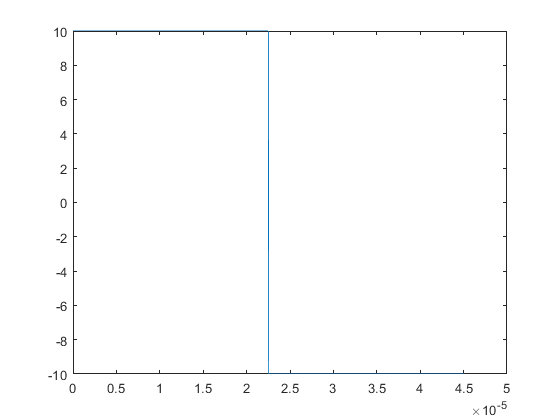


plot(t, x_step)

## definizione fdt

s = tf('s');

H1_dot = 1/(1+tau_step*s)


H1_dot =
 
         1
  ---------------
  1.116e-06 s + 1
 
Continuous-time transfer function.



## definizione risposta gradino

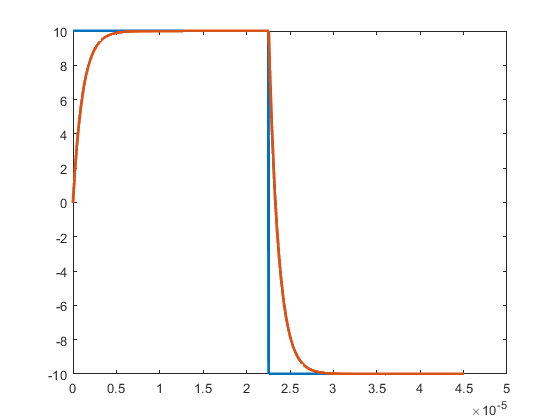

y_step = lsim(H1_dot, x_step, t);

plot(t, x_step, t, y_step, 'linewidth', 2)

## definizione parametri sinusoide

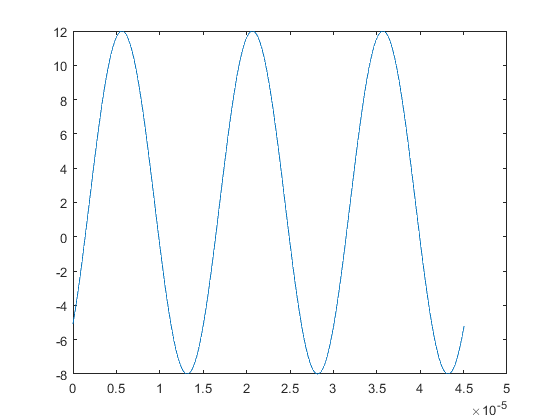

Np = 3;

Tx = Td/Np; 

fx = 1/Tx;

x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4);

plot(t, x_sin)

## definizione fdt

H_dot = 1/(1+tau_sin*s);


## definizione risposta seno

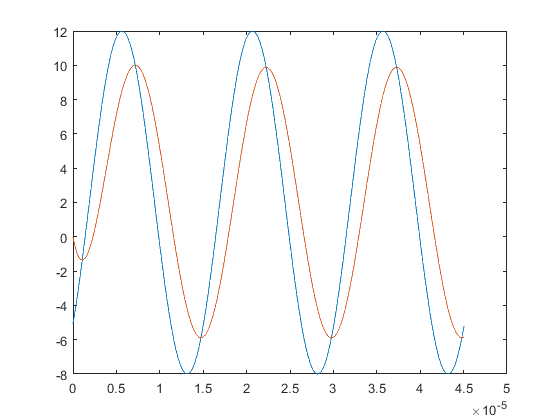

y_sin = lsim(H_dot, x_sin, t);

plot(t, x_sin, t, y_sin)

## 1.4

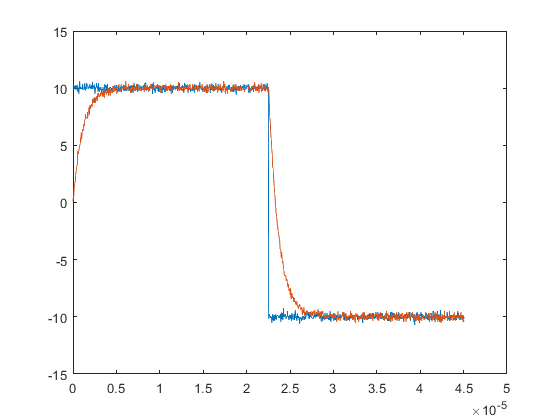

sigma = 0.2;
x_step = Vpp*square(2*pi*t/Td) + randn(N,1)*sigma;

y_step = lsim(H1_dot, x_step, t) + randn(N,1)*sigma;

plot(t,x_step, t, y_step)

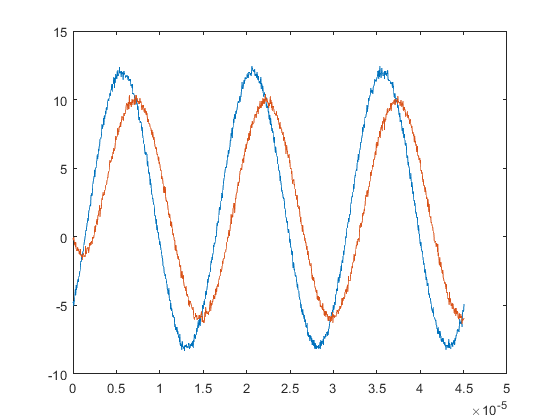


x_sin = 2 + Vpp*sin(2*pi*fx*t - pi/4) + randn(N,1)*sigma;
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;

plot(t,x_sin, t, y_sin)

## PARTE 2

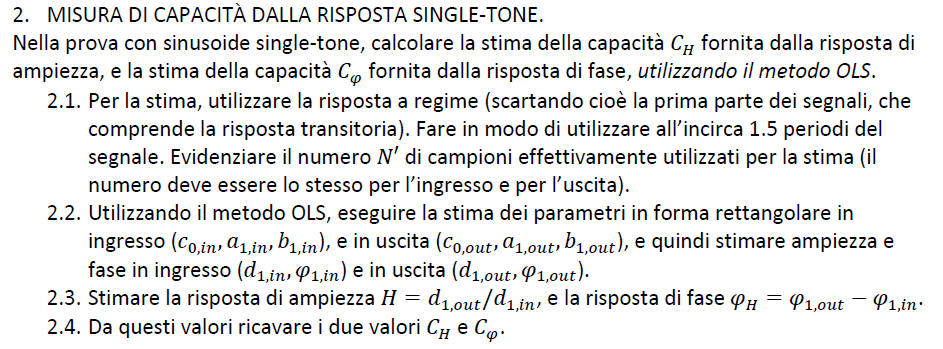

N2 = length(t)/2

N2 =    500



t1 = (N2+1:N)'

t1 =    501
   502
   503
   504
   505
   506
   507
   508
   509
   510


rng('default')

Fx = Np/N; %frequenza digitale
n = (0:N-1)'; %indici dei campioni

x_sin = 2 + Vpp*cos(2*pi*n*Fx - pi/4 - pi/2) + randn(N,1)*sigma; %trasformo seni in coseni
y_sin = lsim(H_dot, x_sin, t) + randn(N,1)*sigma;


xs = x_sin(N2+1:N)

xs =        9.0551
       9.1162
       8.8363
       8.7183
       8.5409
       8.4622
       8.2482
       8.6368
       7.6952
       7.4049


ys = y_sin(N2+1:N)

ys =        9.4949
       9.8966
       9.8943
       9.7863
        9.774
       9.6072
        9.825
       9.4809
       9.4561
       9.7111


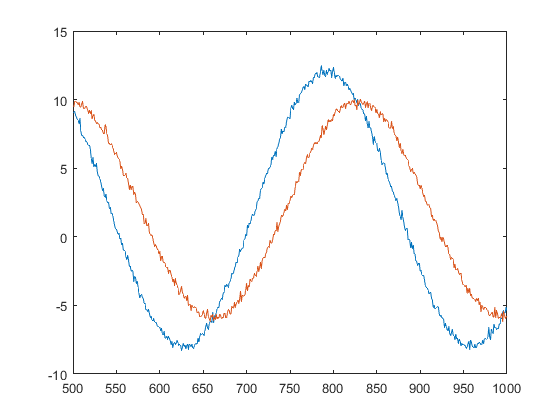



plot(t1, xs, t1, ys)


a1 = cos(-3*pi/4);
b1 = sin(-3*pi/4); 

wt = 2*pi*Fx*t1;

A = [ones(N2,1), cos(wt), -sin(wt)]

A =             1     -0.99982     0.018848
            1     -0.99929      0.03769
            1      -0.9984     0.056519
            1     -0.99716     0.075327
            1     -0.99556     0.094108
            1     -0.99361      0.11286
            1     -0.99131      0.13156
            1     -0.98865      0.15023
            1     -0.98564      0.16883
            1     -0.98229      0.18738


## Stima dei parametri di y


theta_hat_y = (A'*A)^(-1)*A'*ys; %% A\y

c0_hat_y = theta_hat_y(1)

c0_hat_y =        1.9897


a1_hat_y= theta_hat_y(2)

a1_hat_y =       -7.8192


b1_hat_y = theta_hat_y(3)

b1_hat_y =      -0.81223



d1_hat_y = sqrt(a1_hat_y^2 + b1_hat_y^2)

d1_hat_y =        7.8613



phi1_hat_y = atan2(b1_hat_y, a1_hat_y)

phi1_hat_y =       -3.0381


## Stima dei parametri di x

theta_hat_x = (A'*A)^(-1)*A'*xs; %% A\y

c0_hat_x = theta_hat_x(1)

c0_hat_x =        1.9871


a1_hat_x = theta_hat_x(2)

a1_hat_x =       -7.1883


b1_hat_x = theta_hat_x(3)

b1_hat_x =       -6.9166



d1_hat_x = sqrt(a1_hat_x^2 + b1_hat_x^2)

d1_hat_x =        9.9755



phi1_hat_x = atan2(b1_hat_x, a1_hat_x)

phi1_hat_x =       -2.3755


## Stima risposta di ampiezza e di fase

H = d1_hat_y/d1_hat_x

H =       0.78806



phi = phi1_hat_y - phi1_hat_x

phi =      -0.66263


## Ricavo C_H e C_phi


C_H = (sqrt(1-(H^2)/H)*(1/(2*pi*fx*R)))

C_H =    1.4807e-08



C_phi = tan(-phi)*(1/(2*pi*fx*R))

C_phi =    2.5097e-08


## Parte 3

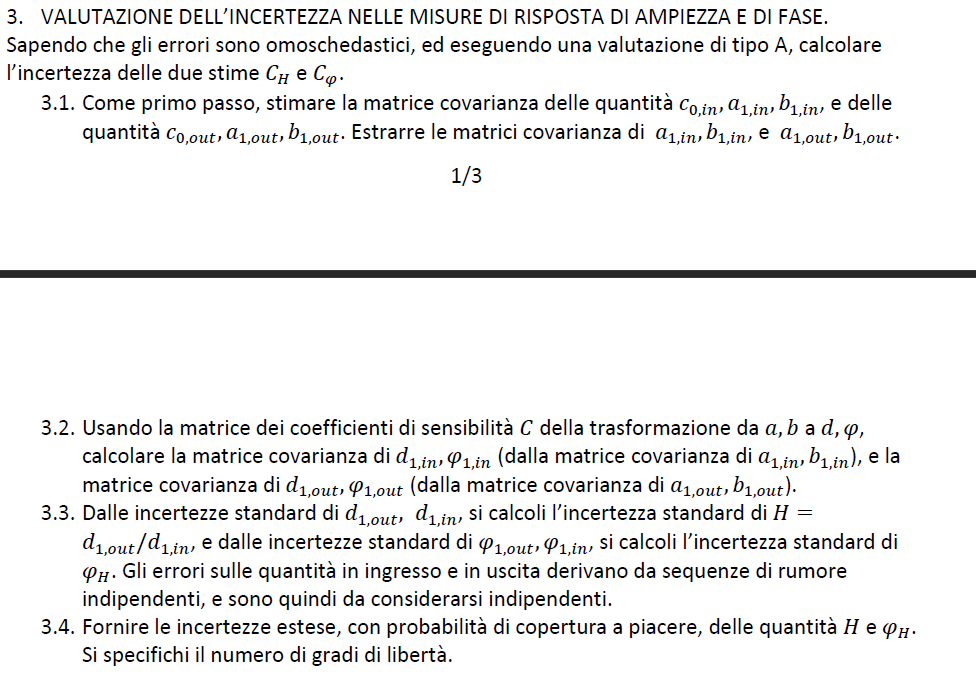

## stima con incertezza di tipo A

x_hat = A*theta_hat_x;

e_hat_x = ys - x_hat

e_hat_x =       0.45113
      0.98705
       1.1214
       1.1524
       1.2815
       1.2584
       1.6221
       1.4261
       1.5516
       1.9591



N_theta_x = length(theta_hat_x)

N_theta_x =      3



nu = N-N_theta_x

nu =    997



sigma2_x = sum(e_hat_x.^2)/nu

sigma2_x =        9.4669


## Stima matrice covarianza in uscita sapendo che gli errori sono omoschedastici


sigma_theta_x = sigma2_x*(A'*A)^(-1)

sigma_theta_x =      0.020808  -8.3232e-05   -0.0088309
  -8.3232e-05     0.037868   3.5324e-05
   -0.0088309   3.5324e-05     0.041616



sigma_theta_x_a1_b1 = sigma_theta_x(2:end, 2:end)

sigma_theta_x_a1_b1 =      0.037868   3.5324e-05
   3.5324e-05     0.041616


## stima con incertezza di tipo A

y_hat = A*theta_hat_y;

e_hat_y = ys - y_hat

e_hat_y =      -0.29742
      0.12382
      0.14375
     0.060725
      0.07618
    -0.060124
      0.19086
     -0.11736
     -0.10353
       0.1928



N_theta_y = length(theta_hat_y)

N_theta_y =      3



nu = N-N_theta_y

nu =    997



sigma2_y = sum(e_hat_y.^2)/nu

sigma2_y =      0.019922



sigma_theta_y = sigma2_y*(A'*A)^(-1)

sigma_theta_y =    4.3788e-05  -1.7515e-07  -1.8584e-05
  -1.7515e-07   7.9689e-05   7.4335e-08
  -1.8584e-05   7.4335e-08   8.7575e-05



sigma_theta_y_a1_b1 = sigma_theta_y(2:end, 2:end)

sigma_theta_y_a1_b1 =    7.9689e-05   7.4335e-08
   7.4335e-08   8.7575e-05


C =     0.0021892    0.0021716     0.002154    0.0021365    0.0021189    0.0021014     0.002084    0.0020665    0.0020491    0.0020318    0.0020145    0.0019973    0.0019802    0.0019631    0.0019462    0.0019293    0.0019125    0.0018958    0.0018792    0.0018627    0.0018464    0.0018302    0.0018141    0.0017981    0.0017823    0.0017666    0.0017511    0.0017358    0.0017206    0.0017056    0.0016907     0.001676    0.0016616    0.0016473    0.0016332    0.0016193    0.0016056    0.0015921    0.0015789    0.0015658     0.001553    0.0015404    0.0015281    0.0015159    0.0015041    0.0014924    0.0014811    0.0014699    0.0014591    0.0014485
    -0.004008   -0.0040058   -0.0040022   -0.0039972   -0.0039907   -0.0039829   -0.0039736   -0.0039629   -0.0039508   -0.0039373   -0.0039224   -0.0039061   -0.0038884   -0.0038694    -0.003849   -0.0038272    -0.003804   -0.0037795   -0.0037537   -0.0037266   -0.0036981   -0.0036683   -0.0036372   -0.0036048   -0.0035712   -0.0035362   -0.0

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.